# **ACM 11 Homework 2, Part 1/2: Solving the 1D heat equation**

## **Instructions**

This assignment is **due Friday, April 16, 11:59pm Pacific Time**. You should read the problem set-up in this file and follow the instructions to write and test your code to solve the heat equation. When you are satisfied with your code in this part, only then move onto Part 2/2, which will ask you to test your code at different time-step and grid spacing sizes. When you are done with both parts, zip all of your files needed to run the code into a single zip and upload to Canvas -- your final zip should include `ACM11_HW2_part1.mlx, ACM11_HW2_part2.mlx, getMatrix.m, forwardEulerLinear.m, backwardEulerLinear.m, `and` reference.mat.`

## Heat equation: Introduction

**Motivation. **The heat equation studies the transport of heat according to the fundamental laws of thermodynamics. It describes how heat moves through an object to change its temperature, and is also used to describe how chemicals diffuse in water and air. It is a fundamental building block in mathematical modeling in applications as diverse as neuron activation modeling, pollutant dispersion in groundwater, and thermal simulations of spacecraft.

**Derivation.** The heat equation can be derived as follows: Fourier's law says that the rate of heat flow is proportional to the temperature change (gradient): $q=-\kappa\frac{\partial u}{\partial x}$. Here $\kappa>0$ is a constant of the ratio, and $q$ is the heat flow rate that describes the "velocity" of the heat transportation. The sign of $q$ describes the direction of the flow (to the left or to the right).

Now if we consider an infinitesimal part $\left[x, x+\delta x\right]$ of the rod, the total extra heat accumulated should be $-q(x+\delta x, t)+q(x, t)$, which is the amount of inward heat minus the outward heat. So the heat accumulation at time t in a unit length around $x$ is $\frac{-q(x+\delta x, t)+q(x, t)}{\delta x}\approx-\frac{\partial q(x, t)}{\partial x}$.

Such heat accumulation is ultimately reflected by the temperature change; that is, $\frac{\partial u}{\partial t}=-\frac{\partial q}{\partial x}$. Putting everything together, we have


$$\frac{\partial u}{\partial t}=-\frac{\partial q}{\partial x}=-\frac{\partial}{\partial x}\left(-\kappa\frac{\partial u}{\partial x}\right)=\kappa\frac{\partial^2 u}{\partial x^2}\,.$$


And therefore, we have the heat equation $\frac{\partial u}{\partial t}=\kappa\frac{\partial^2 u}{\partial x^2}$. The heat equation is a special case of the convection-diffusion-reaction equation we saw in class, the special case of no convection or reaction, just diffusion.

**Initial/boundary-value problem.** We will consider modeling the heat equation in a finite 1D domain of length L, $\left[0, L\right]$. For example, this could model the heat in a long rod or beam. We will take $u=u(x, t)$ to be the temperature at position $x$ and time $t$. We want to find a solution $u\left(x,t\right)$ satisfying the heat equation,

$\frac{\partial u}{\partial t}=\kappa\frac{\partial^2 u}{\partial x^2}$,

in the time interval $\left(0,T\right\rbrack$, subject to the following initial and boundary conditions:


$$\text{Initial condition: }\quad u(x, 0)=f(x)\,.$$



$$\text{Boundary condition 1: }\quad u(0, t)=0\,.$$



$$\text{Boundary condition 2: }\quad u(L, t)=0\,.$$


To do so, we will follow the strategy discussed in class. First we discretize the domain into N spaces (using N+1) grid points. Then, we will use the approximate values of $u$ at these grid points to approximate the second derivative on the right-hand-side of the heat equation. Finally, we will use ODE time-stepping strategies to solve the equation in time. 

## Problem 1: Spatial discretization of $\partial^2/\partial x^2$

The domain $\left[0, L\right]$ is discretized using the following N+1 points: $0= x_0<x_1<\cdots<x_{N-1}<x_N=L$, where $x_i=i/N*L=i\Delta x$ with $\Delta x=L/N$. We only need to find $\left\{u(x_i, t)\right\}_{i=0}^N$ to know about the shape of $u(x, t)$at a given time $t$.

Now we establish a way to calculate $\left\{\frac{\partial^2 u}{\partial x^2}(x_i, t)\right\}_{i=0}^N$ from values of $\left\{u(x_i, t)\right\}_{i=0}^N$.

We will use the following central difference scheme to approximate the derivative at the $N-1$ interior points of our domain.


$$\frac{\partial^2 u}{\partial x^2}(x_i, t)\approx\frac{u(x_{i+1}, t)-2u(x_i, t)+u(x_{i-1}, t)}{(\Delta x)^2}\,,\quad \text{for }i=1,\cdots, N-1\qquad \quad (\mathbf{*})$$


Note that here $u(x_0, t)$ and $u(x_N,t)$are fixed at $0$ by the boundary conditions.

**Problem 1a: implementing central difference for the second spatial derivative.**

We set the unknown values $\left\{u(x_i, t)\right\}_{i=1}^{N-1}$ as the $(N-1)\times 1$ vector $\mathbf{u}(t)$, and the right hand side of interest $\left\{\frac{\partial^2 u}{\partial x^2}(x_i, t)\right\}_{i=1}^{N-1}$ as the $(N-1)\times 1$ vector $\mathbf{v}(t)$.

In the provided skeleton code file, `getMatrix.m`, use the inputs $L$ and $N$ and write code to output an $(N-1)\times (N-1)$ matrix $A$, so that we always have $\mathbf{v}(t) =\mathbf{Au}(t)$ by our scheme $(\mathbf{*})$ for all interior points. Here $\mathbf{Au}(t)$ is the matrix-vector product between $\mathit{\mathbf{A}}$ and $\mathbf{u}\left(t\right)$. Recall that at the boundaries, the solution is zero - this will help you handle the first and last rows of your matrix. To receive full points for efficiency, your code should not use any loops - the `diag` command is your friend here. 

**Problem 1b: testing your central difference implementation.**

Now test the correctness of your matrix: since $\frac{\partial^2 }{\partial x^2}\sin\pi x=-\pi^2\sin\pi x$, please try using the matrix $A$ to get the second derivative of $\sin \pi x$ at grid points $\left\{x_i\right\}_{i=1}^{N-1}$, and compare it with the ground-truth. Define the error at grid $x_i$ as $e_i=-\pi^2\sin \pi x_i - v_i$ for $i=1, \cdots, N-1$, and use the Euclidean norm multiplied by $\sqrt{\;\Delta \;x}$ to measure the total error $\text{err}=\sqrt{\Delta x}\cdot\|e\|_2$.

Try $\Delta x=\left\{1\text{e-}2, 1\text{e-}3, 1\text{e-}4\right\}$ and plot the error $\text{err}$ against the spatial discretization size $\Delta x$ (use **logscale** for both $x$-axis and$y$-axis) below. Include a figure title and axis labels. 

We assume that $L=1$.

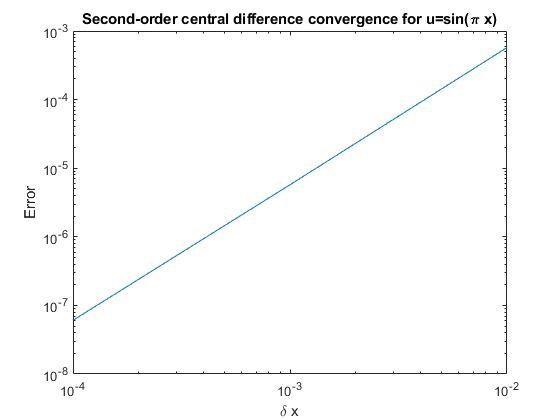

clear % always good to clear workspace before running code, so no stray variables are around to mess things up

L = 1;
dx_list = [ 1e-2 1e-3 1e-4];

err = zeros(length(dx_list),1);
for i = 1:length(dx_list)
    dx = dx_list(i);
    
    % build a computational grid of interior points for each dx in the loop
    x = linspace(0,1,L/dx+1);
    x_int = x(2:end-1);
    % call getMatrix to get 
    % A
    A = getMatrix(1/dx,1);
    % apply A to u = sin(pi*x)
    u = sin(pi*x_int);
    v = A*transpose(u);
    % calculate and store the error as defined above
    err(i) = norm(-pi^2*transpose(u)-v)*sqrt(dx);
end

% plot the error vs. dx in a loglog plot. Include axes labels and a figure
% title
loglog(dx_list,err);
title('Second-order central difference convergence for u=sin(\pi x)');
xlabel('\delta x')
ylabel('Error') 

**Problem 1c: Order of accuracy of central difference approximation**

Based on your error plot, tell us by what factor the error shrinks when the grid spacing shrinks by a factor of 10. What does this tell us the order of accuracy of the central difference approximation is?

fprintf('Since the error shrinks by a factor of 100 when grid shrinks by \n a factor of 10, we can see that the approximation is \n second-order accurate')

Since the error shrinks by a factor of 100 when grid shrinks by 
 a factor of 10, we can see that the approximation is 
 second-order accurate

## **Problem 2: approximating the initial-value problem using Forward Euler**

Now that we have the spatial discretization and matrix $\mathbf{A}$ to represent the right-hand side of the heat equation, our problem can now be viewed as the ODE:


$$\dot{\mathbf{u}}(t) = \kappa \mathbf{Au}(t) $$


where we recall that  $\mathbf{u}(t)$ is an $(N-1)\times 1$ vector of the unknown values $\left\{u(x_i, t)\right\}_{i=1}^{N-1}$.

We first try to solve this equation using forward Euler.

Suppose we want compute $\mathbf{u}(T)$. We set $0=t_0<t_1<\cdots<t_{K-1}<t_K=T$, where $t_j=\frac{T}{K}j=j\Delta t$ with $\Delta t=T/K$. Let $\mathbf{u}_j \approx  \mathbf{u}(t_j)$ be the discrete-time approximation of $\mathbf{u}(t)$.

The forward Euler method solves the ODE by $\frac{\mathbf{u}_{j+1}-\mathbf{u}_j}{\Delta t}=\kappa \mathbf{ Au}_j$, which simplifies to


$$\mathbf{u}_{j+1} = \mathbf{u}_j+\kappa\Delta t  \mathbf{Au}_j=(\mathbf{I}+\kappa\Delta t \mathbf{A})\mathbf{u}_j\,.$$


Let us assume the initial condition is given by $u_{\rm init}(x)=\sin\left(\frac{\pi x}{L}\right) + 2\sin\left(\frac{2\pi x}{L}\right)+0.4\sin\left(\frac{11\pi x}{L}\right)$.

We further assume $\kappa=0.02$, $L=1$, $T=1$ and $N=100, K = 1000$.

Complete the provided skeleton code file `forwardEulerLinear.m`, which takes inputs $u_{\textrm{init}} ,\kappa \;,A,\Delta \;t,$ and $T$, so that it integrates the ODEs using the forward Euler method and outputs the solution at the final time, $\mathbf{u}(T)$. In the code block below, set-up the computational grid of interior points for $N=100$, compute the initial condition $\mathbf{u}(0) = \mathbf{u}_{\rm init}$ at the computational grid, and then call your forward Euler function to get the approximation to $\mathbf{u}\left(T\right)$. Plot $\mathbf{u}(T)$ and $\mathbf{u}(0) = \mathbf{u}_{\rm init}$ in the same figure. Include a figure title, axis labels, and legend. To check your work: the second derivative diffusion operator is a smoothing one, meaning lumps in the equation should smooth out over time. Do you observe that $\mathbf{u}(T)$ is much smoother than $\mathbf{u}(0)$? If not you likely have an issue with your implementation.

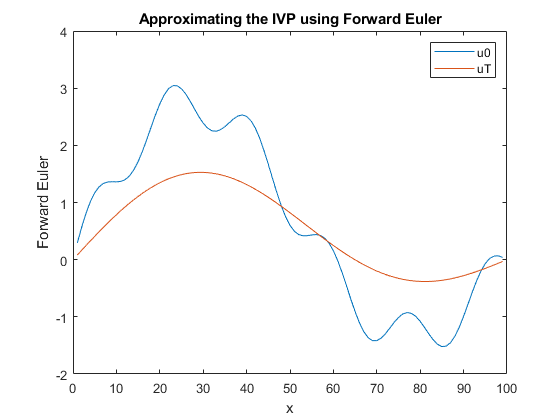

kappa = 0.02;
L = 1;
T = 1;
N = 100;
K = 1000;

dt = T/K;

% make a computational grid of N-1 interior points for x
x = linspace(0,1,N+1);
x_int = x(2:end-1);
% call getMatrix to get the matrix X
A = getMatrix(N,L);
% compute the initial condition on your computational grid
u0 = sin(pi*x_int/L)+2*sin(2*pi*x_int/L)+0.4*sin(11*pi*x_int/L);
% call your forward Euler solver to get the solution at final time
uT = forwardEulerLinear(transpose(u0), kappa, A, dt, T);
% plot the initial and final solution using forward Euler on the same axis.
% Label your axes, use a legend, and include a figure title
plot(u0)
hold on
plot(uT)
hold off

title('Approximating the IVP using Forward Euler')
xlabel('x')
ylabel('Forward Euler')
legend("u0", "uT")

## **Problem 3: approximating the IVP using backward Euler**

Now we solve the equation by the backward Euler method. Backward Euler solves the ODE by $\frac{\mathbf{u}_{j+1}-\mathbf{u}_j}{\Delta t}=\kappa\mathbf{Au}_{j+1}$, which simplifies to


$$\mathbf{u}_{j+1}-\kappa\Delta t  \mathbf{Au}_{j+1}=\mathbf{u}_{j}\Longrightarrow \mathbf{u}_{j+1} =(\mathbf{I}-\kappa\Delta t \mathbf{A})^{-1}\mathbf{u}_j\,.$$


Now complete the provided skeleton code file back`wardEulerLinear.m`, which takes inputs $u_{\textrm{init}} ,\kappa \;,A,\Delta \;t,$ and $T$, so that it integrates the ODEs using the *backward Euler* method and outputs the solution at the final time, $\mathbf{u}(T)$. As in Problem 2, use your backward Euler function to get the approximation to $\mathbf{u}\left(T\right)$ using the same settings as in Problem 2. Plot $\mathbf{u}(T)$ from both the forward Euler and the backward Euler methods in the same figure. Include figure titles, axis labels, and legends, and use a different line style for the two plots so we can see two lines. The lines should essentially be on top of each other!

% call your backward Euler solver on the same initial condition as above 
uTb = backwardEulerLinear(transpose(u0), kappa, A, dt, T);

Unrecognized function or variable 'u0'.

% plot the forward Euler and backward Euler solutions at T = 1 vs. x in the
% same axes. Label axes, use legend, include title.
plot(uT)
hold on
plot(uTb, ['.'])
hold off

title('Approximating the IVP using Forward and Backward Euler')
xlabel('x')
ylabel('Approximation')
legend("Forward Euler", "Backward Euler")